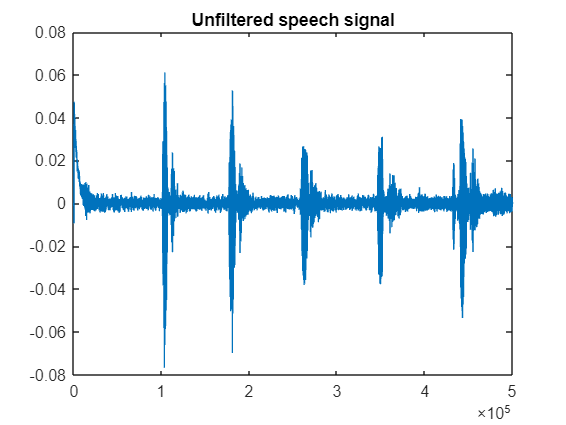

input = "C1Connor.m4a";
[y, fs] = audioread("Voice Data\"+input);

%make spectrogram of first half-million data points
word = y(1:500000);
plot(word)
title("Unfiltered speech signal");

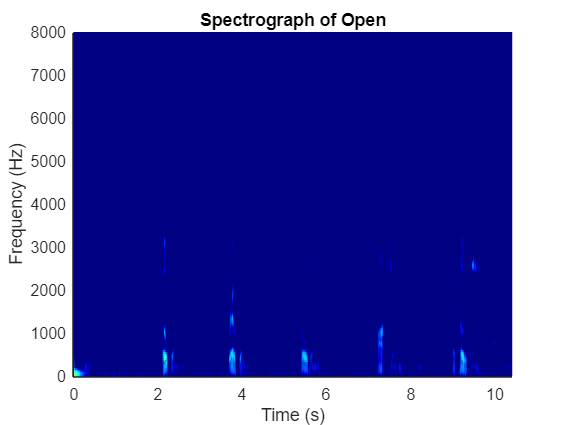

ans = 48000

spectrograph(word,fs,"Spectrograph of Open")

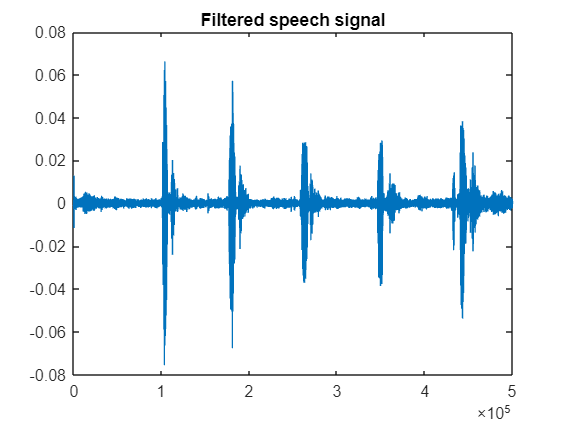

%apply highpass filtering
[word, a] = highpass(word, 200, fs);
%[y, a] = highpass(y, 200, fs);
y = word;
plot(y)
title("Filtered speech signal");

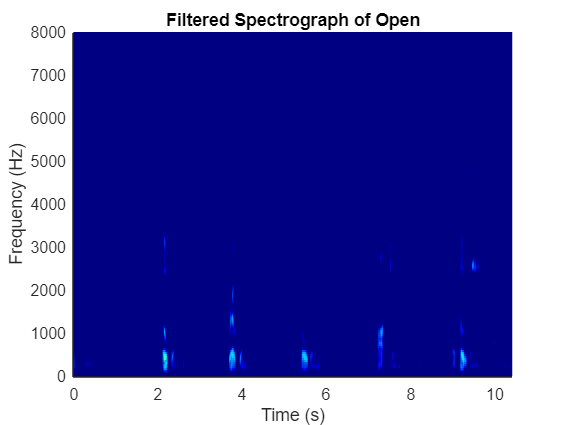

ans = 48000

spectrograph(word,fs,"Filtered Spectrograph of Open")

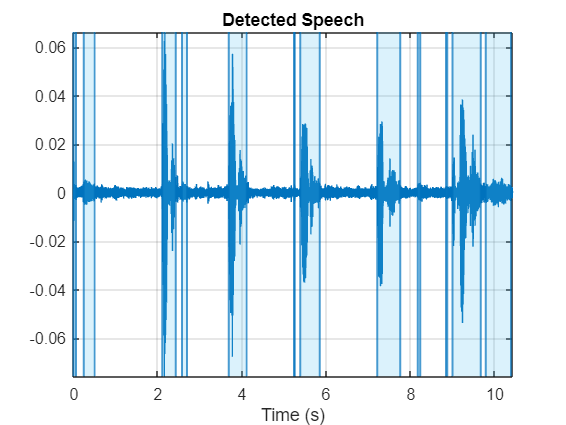

% Now smooth with a Savitzky-Golay sliding polynomial filter
%windowWidth = 27;
%polynomialOrder = 3;
%y = sgolayfilt(y, polynomialOrder, windowWidth);
%plot(y);

%configure detectspeech
windowDuration = 0.01; % seconds
numWindowSamples = round(windowDuration*fs);
win = hamming(numWindowSamples,'periodic');

percentOverlap = 35;
overlap = round(numWindowSamples*percentOverlap/100);

mergeDuration = 0.1;
mergeDist = round(mergeDuration*fs);

detectSpeech(y,fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist)

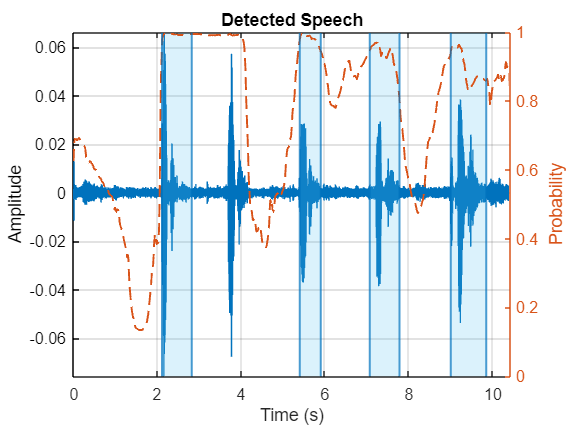

%detectspeechnn is trash
detectspeechnn(y, fs, ApplyEnergyVAD=true, ActivationThreshold=.83, DeactivationThreshold=.80)

%get speech indices
thresholds = [.015, .035];
[indices, thresholds] = detectSpeech(y,fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist, "Thresholds", thresholds)

indices =            1        2808
       11544       24024
      101088      116376
      123552      129168
      176904      197184
      251160      252096
      258336      280488
      346008      372216
      392184      394992
      424320      425880


thresholds =     0.0150    0.0350


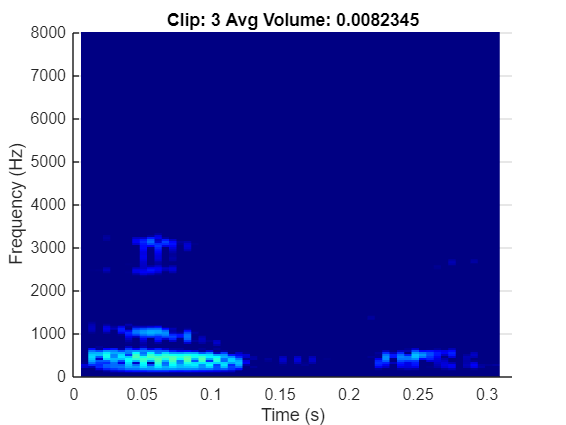

ans = 48000

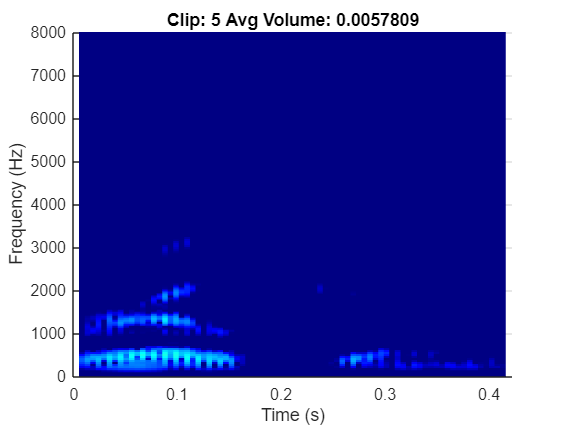

ans = 48000

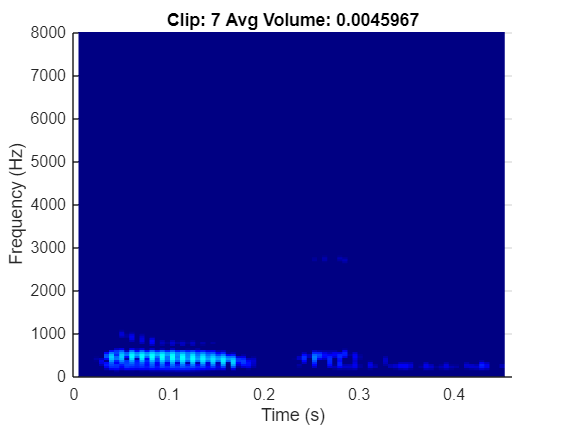

ans = 48000

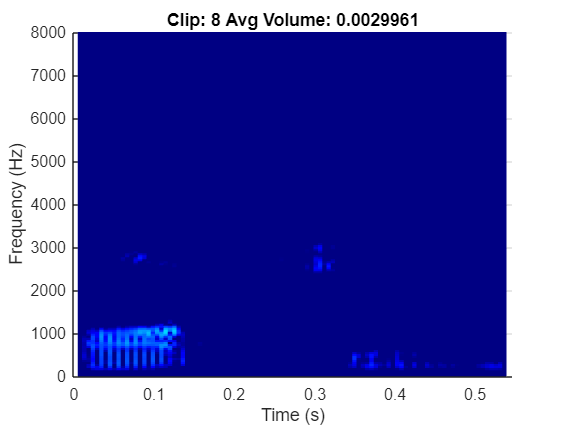

ans = 48000

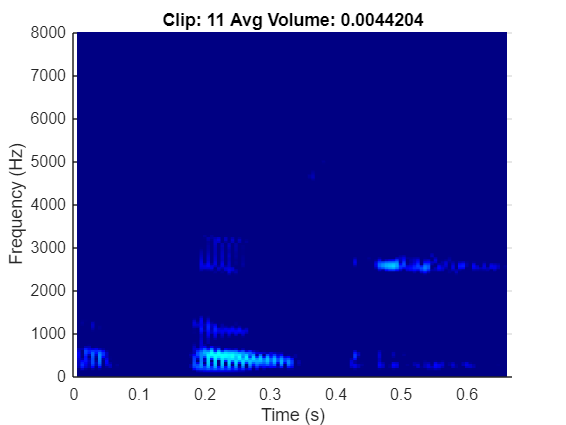

ans = 48000

%split speech signal and remove erroneus speech detections
for i = 1:length(indices)
    if(indices(i,2) - indices(i,1) > 1000)
        clip = y(indices(i,1):indices(i,2));
        avg = avgVol(clip);
        if(avg > .0019)
            spectrograph(clip, fs, "Clip: " + i + " Avg Volume: " + avg)
            %filename = "Voice Data\Clips\" + input + "_" + i + ".wav";
            %audiowrite(filename, clip, fs);
        end
    end
end

function avg = avgVol(x)
    avg = sum(abs(x(:)))/numel(x); 
end
